 clear all
 close all


## Construction du système discret

%dimensions du domaine
%ordre 2 centré
lx = 1;
ly = 1;

%nombre de points dans chaque dimension
Nx = 50;
Ny = 50;
% pas de discretisation
h = lx/(Nx+1);
k = ly/(1+Ny);

a = k^2/(2*(h^2 + k^2));
b = h^2/(2*(h^2 + k^2));
c = (k^2)*(h^2)/(2*(h^2 + k^2));

% construction du système linéaire
temp = a*ones(Nx-1,1);
A = eye(Nx) - diag(temp,1) - diag(temp,-1);
B = b*eye(Nx);

M = zeros(Nx*Ny);
M(1:Nx,1:Nx) = A;
M(1:Nx,Nx+1:2*Nx)=-2*B;
for i=2:Ny
    M((i-1)*Nx+1:i*Nx,(i-1)*Nx+1:i*Nx) = A;
    M((i-1)*Nx+1:i*Nx,(i-2)*Nx+1:(i-1)*Nx) = -B;
    if i < Ny
        M((i-1)*Nx+1:i*Nx,i*Nx+1:(i+1)*Nx) = -B;
    end
end
%construction second membre
N = zeros(Nx*Ny,1);
x=linspace(h,lx,Nx);
y=linspace(k,ly,Ny);

for i=1:Nx
    N(i) = 2*k*b*g(x(i),lx,ly);
end
N

N =    -0.0019
   -0.0038
   -0.0057
   -0.0076
   -0.0095
   -0.0113
   -0.0131
   -0.0148
   -0.0165
   -0.0181


 
for j=1:Ny
    for i=1:Nx
        p = i + (j-1)*Nx;
        N(p)= N(p) - c*f(x(i),y(j),lx,ly);
    end 
end 

%résolution

U = M\N;
% affichage de la solution 
u=zeros(Nx+2,Ny+2);
Uth = u;
for j=1:Ny
    for i = 1:Nx
        p= i +(j-1)*Nx;
        u(i+1,j+1)=U(p,1);
        Uth(i+1,j+1) = uth(x(i),y(j),lx,ly);
    end
end
u

u =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0035    0.0073    0.0111    0.0148    0.0185    0.0222    0.0257    0.0291    0.0325    0.0357    0.0387    0.0416    0.0443    0.0469    0.0493    0.0515    0.0534    0.0552    0.0568    0.0581    0.0592    0.0601    0.0607    0.0611    0.0613    0.0612    0.0609    0.0604    0.0596    0.0586    0.0574    0.0560    0.0543    0.0525    0.0504    0.0482    0.0458    0.0432    0.0404    0.0375    0.0345    0.0314    0.0281    0.0248    0.0213    0.0179    0.0143    0.0108    0

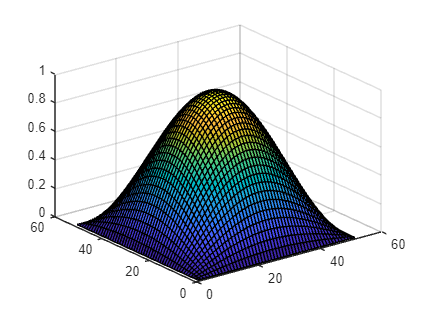

%[X,Y] = meshgrid(0:h:lx,0:k:ly)

%erreur eps
eps = abs(u-Uth);
surf(u)

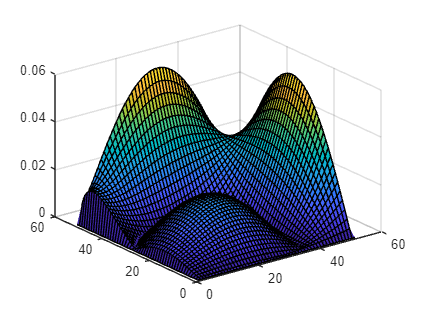

surf(eps)

N

N =    -0.0019
   -0.0038
   -0.0057
   -0.0076
   -0.0094
   -0.0113
   -0.0130
   -0.0148
   -0.0164
   -0.0180
